# EEET-425-2245  Digital Signal Processing Exam 02

## Name: Jonathan Sumner

## Instructions

**This exam consists of 4 problems worth 20, 20, 30 and 30 points each.  Complete all the problems in this MATLAB Live Script by entering your code and creating plots as requested or by typing your answers into the space provided.  For problem 2, Convolution you will need to show your work on a separate document (e.g. a spread sheet) or on paper.**

**When you have completed your exam export this MATLAB Live Script to a ****PDF**** and submit both files to the Assignments section of myCourses.  Also upload any other files for Problem 2.  If you completed Problem 2 on paper either use a scan application or get a good picture of your exam and convert it to a PDF file.  A scan is preferred.  If you used an excel spread sheet, submit your spread sheet file.**

**To export your Live Script File to a PDF click the down arrow below the Save Icon and select Export to PDF.    Always double check your exported PDF to see that it is rendered correctly.**

**You have approximately 3 hours to complete this exam.  The exam will not automatically close on you, but your time will be monitored.**

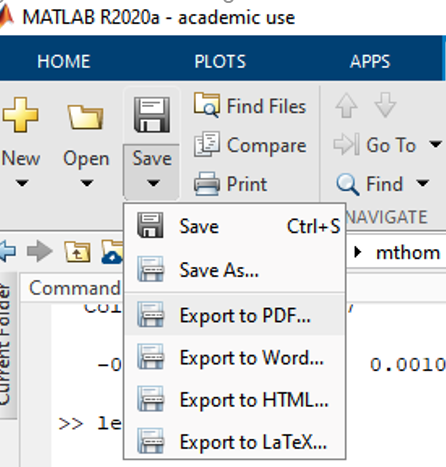

**Submit all files to the Assignments Section of myCourses.  ****DO NOT SUBMIT A ZIP FILE!**

**I will be on-line during class time and office hours following class.  Use the links in myCourses to the class ZOOM meeting and Office Hours.**

**https://rit.zoom.us/j/96084746206?pwd=J2bz3W5ooOmWbh6W2u4jMLjp7MG230.1**

[**DSP Office Hours**](https://rit.zoom.us/j/96084746206?pwd=J2bz3W5ooOmWbh6W2u4jMLjp7MG230.1)

**Meeting ID: 960 8474 6206**

**Passcode: mwtoffice**

## Problem 1 -- Linear Systems (20 points)

#### Two discrete signals a[n] and b[n] are shown below.  Each are 8 samples long.

#### a[n] = [-1, -2, -3, -4, 4, 3, 2, 1]

#### b[n] = [ 1, 0, -1, 0, 1, 0, -1, 0 ]

#### For this problem, you can add additional samples with a value of zero to the beginning or the end of the signal as needed.  Truncate your result to 8 samples in all cases.

#### Find the following results considering the properties of linear systems

#### 1A) (xx Pts)   -5a[n]

PLACE YOUR SOLUTION HERE

-5a[n] = [5, 10, 15, 20, -20, -15, -10, -5]

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

#### 1B) (5 Pts) -3a[n-2]

PLACE YOUR SOLUTION HERE

-3a[n-2] = [0, 0, 3, 6, 9, 12, -12, -9]

#### 1C) (5 Pts) 2b[n+1]

PLACE YOUR SOLUTION HERE

2b[n+1] = [0, -2, 0, 2, 0, -2, 0, 0]

#### 1D) (5 Pts)  -3a[n-2] + 2b[n+1]

PLACE YOUR SOLUTION HERE

-3a[n-2] + 2b[n+1] = [0, -2, 3, 8, 9, 10, -12, -9]

## Problem 2 -- Convolution and Linearity (20 points)

#### The system shown below consists of two linear filters that have the same impulse response h[n].  The output of the filters are summed together resulting in the output sequence y[n].  At the input to the filters are two different gain blocks and two different signals.  

#### The impulse response of both filters is the same and is h[n] = [ -1, 1, 0 , 1].

#### The input x1[n] = [1, 4,-3, 4, -1, 2 ] and the input x2[n] = [-1, 3, 2, -1, 4, 2].

#### The value of k1 = 3 and the value of k2 = 2

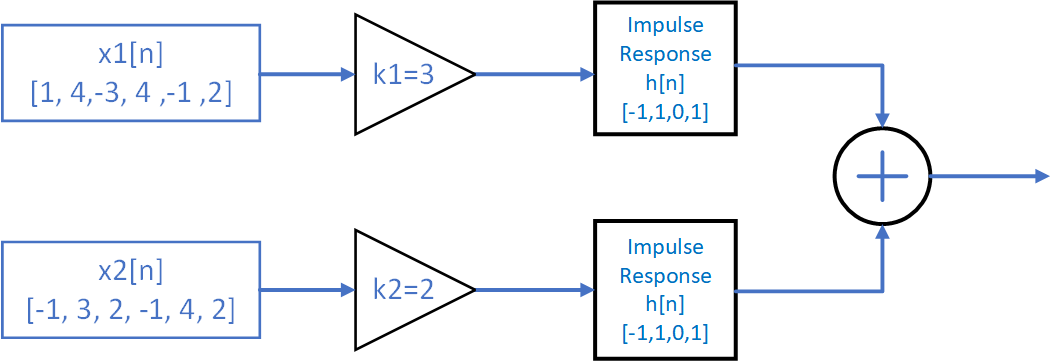

#### 2A) (5 Pts) What are the two properties that systems must have to be a linear system? Type your answer below.

Additivity and Homogenenity

#### 2B) (5 Pts)  What will be the length of the output sequence y[n]? Type your answer below.

%  PUT YOUR SOLUTION HERE
M = length(x[n])
N = length(h[n])
L = M + N - 1
L = 6 + 4 - 1
L = 9

#### 2C) (10 Pts)   Compute the output y[n] of the system of linear filters for the two input sequences x1 and x2.  You do NOT need to use MATLAB to solve this.  You may do this on paper or in a spreadsheet.  You must show me that you know how to perform convolution. You may NOT use the MATLAB 'conv' function in your answer however, you may use the function to check your work.

#### HINT:  Save yourself some time by considering the use of the properties of a linear system to make the computation easier.  Show all your work in computing the output.   You may upload your results scanned from a separate sheet of paper or use an excel spread sheet.

%  PUT YOUR SOLUTION HERE
y[n] = [-1, -17, 23, -14, 23, -10, 20, 5, 10]

## Problem 3 --  Moving Average Filters (30 points)

#### You are sampling a patient's breathing with a temperature sensor.  You are picking up some unwanted noise on your signal, possibly from the USB power supply.  You can't get rid of it by changing your hardware or moving wires, etc..  You want to get rid of the noise, but you want to retain the signal integrity.   You decide to use a moving average filter (MAV) to remove the noise as part of the signal processing.

#### Perform the following steps and anser the questions about moving average (MAV) filters

#### 3A) (5 Pts) Load the exam file 'Exam_02_Problem_3_Signal.mat' from myCourses.  This will load a variable named 'outData' into the workspace.  The variable 'outData' has 1000 rows and 2 columns.  The first column of 'outData' is the sample number.  The second column of 'outData' is the noisy temperature signal (with the average removed).  Plot the temperature signal vs the sample number in MATLAB.  Be sure to title the graph and label the X and Y axes.

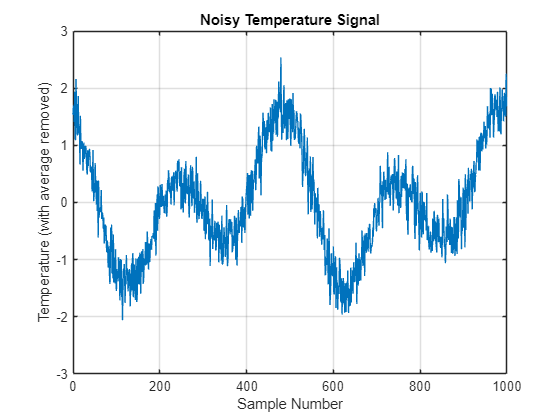

%  PUT YOUR SOLUTION HERE
load('Exam_02_2245_Problem_03.mat');
sampleNum  = outData(:,1);
tempSignal = outData(:,2);

figure;
plot(sampleNum, tempSignal);
title('Noisy Temperature Signal');
xlabel('Sample Number');
ylabel('Temperature (with average removed)');
grid on;

#### 3B) (5 Pts)  Why might you choose a MAV filter for this application vs a Windowed SINC Filter?

#### TYPE YOUR ANSWER HERE

The MAV is a simple, efficient, and effective lowpass filter for smoothing out broad‐band noise


#### 3C) (5 Pts) Using MATLAB, create an impulse response of a moving average filter of length of your choice.  Write your code so that you can easily change the length of the impulse response as you may need to adjust the filter length later.  Plot the impulse response using the 'stem' command

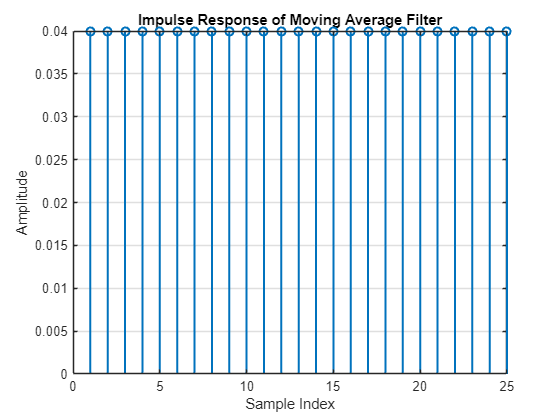

%  PUT YOUR SOLUTION HERE
filterLength = 25;

% Generate the impulse response for a moving average filter of length M.
hMAV = ones(1, filterLength) / filterLength;

% Plot using stem
figure;
stem(hMAV, 'LineWidth', 1.5);
title('Impulse Response of Moving Average Filter');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

#### 3D) (5 Pts) Using MATLAB and the 'freqz' function compute the frequency response of the filter.  Compute the frequency using 2000 samples in the frequency domain.  Plot the frequency response of the filter.

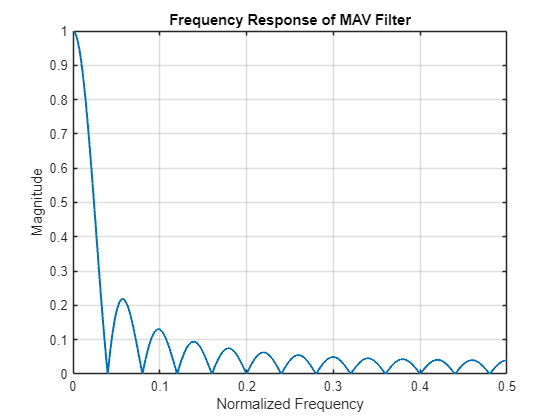

%  PUT YOUR SOLUTION HERE
[H, W] = freqz(hMAV, 1, 2000);

figure;
plot(W/(2*pi), abs(H), 'LineWidth',1.5);  % normalized frequency on x-axis
title('Frequency Response of MAV Filter');
xlabel('Normalized Frequency');
ylabel('Magnitude');
grid on;

#### 3E) (5 Pts) Filter the temperature signal using the impulse response of the filter that you created in step C.  You may use MATLAB functions for this problem.  Plot the output of the filter. Be sure to add an appropriate title and axes labels.  Adjust the length (part C) of the filter so that the filter removes the noise, but preserves the signal integrity.  This is a judgement call.

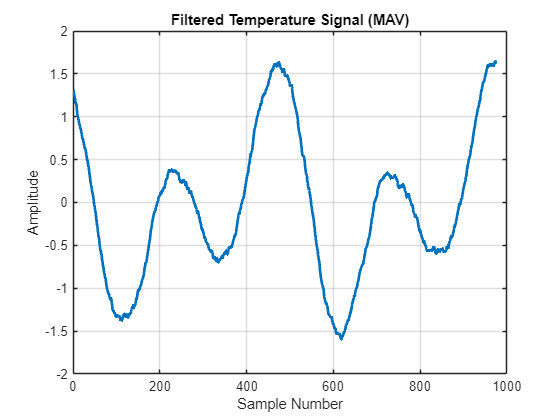

%  PUT YOUR SOLUTION HERE
filteredSignal = conv(tempSignal, hMAV);

M = filterLength;
filteredNoEnds = filteredSignal(M : end - (M - 1));

figure;
plot(filteredNoEnds, 'LineWidth', 2);
title('Filtered Temperature Signal (MAV)');
xlabel('Sample Number');
ylabel('Amplitude');
grid on;

#### 3F) (5 Pts) For the length of the filter that you selected how long are the end effects that occur at the beginning and the end of the filter output sequence?

%  PUT YOUR SOLUTION HERE
The end effects each have length M - 1 and with the filter length being 25, each end effect is 24 samples

## Problem 4 --  Windowed SINC FIR Filters (30 points)

#### Again, you are sampling a patient's breathing with a temperature sensor.  You are picking up some unwanted interference on your signal that is a sinewave at a frequency equivalent to 65 BPM.  You can't get rid of it by changing your hardware or moving wires, etc..  You want to get rid of the interference, but you want to retain the signals from 0 BPM to 40 BPM.   You decide to filter the signal to remove the interference as part of the signal processing.

#### 4A) (5 Pts) What type of filter would you use to remove the interfering tone while retaining the desired signals. lowpass, highpass, bandpass, or bandstop?  Type your answer below.

A Lowpass filter is appropriate for removing the single unwanted tone at 65 BPM

#### 4B) (5 Pts) Load the exam file from myCourses 'Exam_02_2245_Problem_02.mat'.  This file will load a variable 'outData' into the work space.  This variable has two columns each of length 256.  The first column is the sample number and the second column is the signal data.  Create two variables with appropriate names from these columns.  Plot the signal versus the sample number.  Use an appropriate title and x and y axes labels.

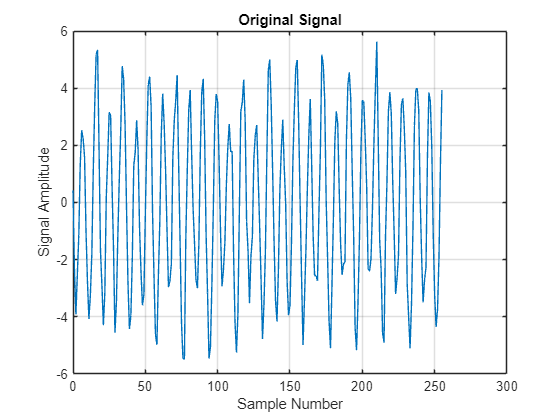

%
%  Put your MATLAB solution here
%
load('Exam_02_2245_Problem_04.mat');

sampleNumber = outData(:,1);
signalData   = outData(:,2);

figure;
plot(sampleNumber, signalData);
title('Original Signal');
xlabel('Sample Number');
ylabel('Signal Amplitude');
grid on;

#### 4C) (10 Pts) Using the FIR_Designer tool, create a filter to remove the undesired tone at 65 BPM from the desired signals at 40 BPM or less.  Adjust the filter design parameters until the undesired tone is attenuated to at least one-half the magnitude of the desired tone (on a linear scale).  More attenuation is OK.  You may have to do this iteratively.  Plot the frequency response of the filter you designed on a linear scale versus the absolute frequency in BPM.   Display only the frequencies from 0 to the Nyquist frequency.

#### Tips:

#### To suppress the FIR_Designer tool from plotting the output use the Name/Value Pair argument 'PlotResponses',false (no quotes around false)

#### To suppress the MATLAB print out of the impulse response use 'PrintMATLAB', false (no quotes around false).

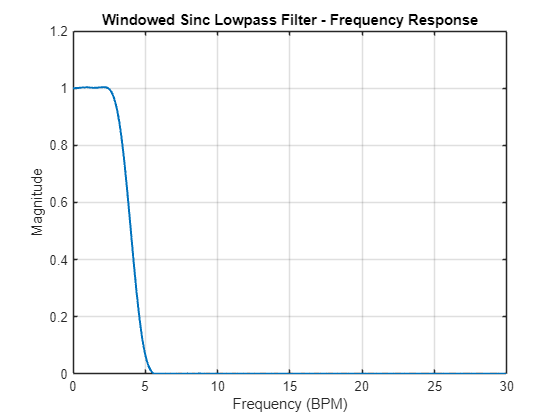

%  Example
%  hSINC = FIR_Designer('nOrder', xxOrder, 'cutBPM', xxCorner, 'PlotResponses',false,'PrintMATLAB', false); 
%
%
%  Put your MATLAB solution here 
%
filtOrder = 64;
cutBPM = 40;

hSINC = FIR_Designer('nOrder',     filtOrder, ...
                     'cutBPM',     cutBPM, ...
                     'Window',     'Hamming', ...
                     'PrintHeader', false, ...
                     'PlotResponses',  false, ...
                     'PrintMATLAB',    false);

nSamples = 512;
[Hf, Wf] = freqz(hSINC, 1, nSamples);

figure;
plot(Wf/(2*pi)*60, abs(Hf), 'LineWidth',1.5); 
title('Windowed Sinc Lowpass Filter - Frequency Response');
xlabel('Frequency (BPM)');
ylabel('Magnitude');
grid on;

#### 4D) (10 Pts) Apply the filter that you designed to the input signal using time domain convolution.  You may use the MATLAB 'conv' function.  Plot the original signal and the resulting time domain signal on the same graph.  Add appropriate titles and axes labels.

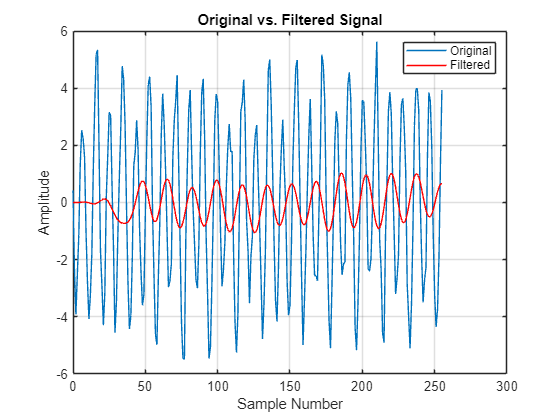

%
%  Put your MATLAB solution here 
%
filteredOutput = conv(signalData, hSINC);

figure;
plot(sampleNumber, signalData, 'DisplayName','Original');
hold on;

plot(sampleNumber, filteredOutput(1:256), 'r', 'DisplayName','Filtered');
title('Original vs. Filtered Signal');
xlabel('Sample Number');
ylabel('Amplitude');
legend;
grid on;